clear, close all, clc

Der ønskes et eksperiment udført med 2 temperaturer, 3 operatorer og tre cyklustider. Der testes 3 gange med hver kombination.

load('dataset_problem_14_11.mat')

Opgave a)

Forklar og test hypoteserne med alpha = 0.05.

Der er syv mulige hypoteser:

Ingen A-, B- og C-effekter, og ingen interaktion mellem A/B, A/C, B/C, A/B/C.

sz = size(data)

sz =     18     6


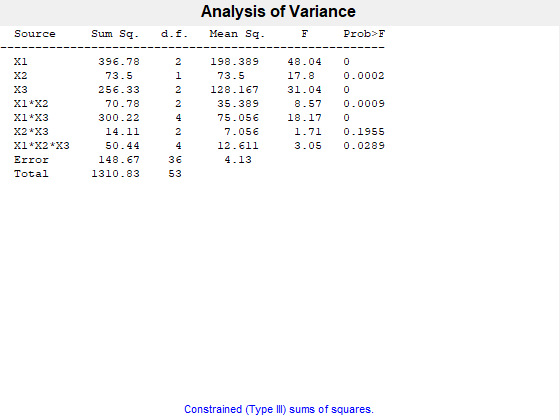

P =     0.0000
    0.0002
    0.0000
    0.0009
    0.0000
    0.1955
    0.0289


[V,g1,g2,g3] = deal(zeros(1,0));
for i = 1:sz(1)
    for j = 4:6
        V = [V data(i,j)];
        g1 = [g1 data(i,1)];
        g2 = [g2 data(i,2)];
        g3 = [g3 data(i,3)];
    end
end
g = {g1,g2,g3};
P = anovan(V,g,'model','full')


% Kun faktoren temperatur OG operator forkastes ikke
% og der er altså signifikant sammenhæng mellem
% alle andre.